# Experiment with ConvMixer model

## Load data

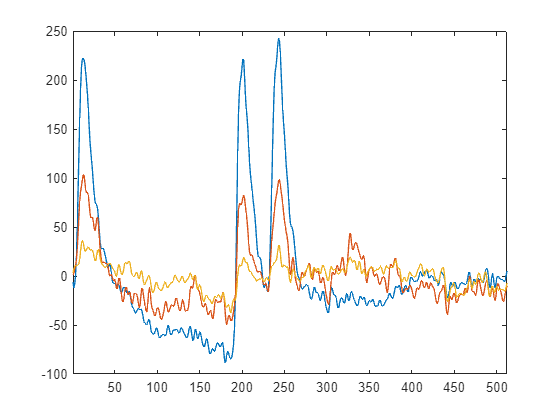

XTrain = load(fullfile('DataSet','HyperparameterSearch','Train','XSearchTrain.mat')).XSearchTrain;
YTrain = load(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat')).YSearchTrain;

XTest = load(fullfile('DataSet','HyperparameterSearch','Test','XSearchTest.mat')).XSearchTest;
YTest = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;


XTrain = selectChannels(XTrain,[1 2 3]);
XTest = selectChannels(XTest,[1 2 3]);

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};

figure;i = 1;
plot(XTrain{i}');
xlim([1 size(XTrain{i},2)]);

## Hyper-parameter search

error occour
|===============================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Depth |   numFilters | HiddenDimens-|  filterSizeS | paddingSizeS | dropoutLayer-| miniBatchSize| learningrate |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | ion          |              |              | Regularizati |              |              |
|===============================================================================================================================================================================================|
|    1 | Best   |           1 |      1.0336 |           1 |           1 |            5 |            7 |           30 |            3 |            3 |     0.018905 |           54 |     0.034971 |
error occour
|   

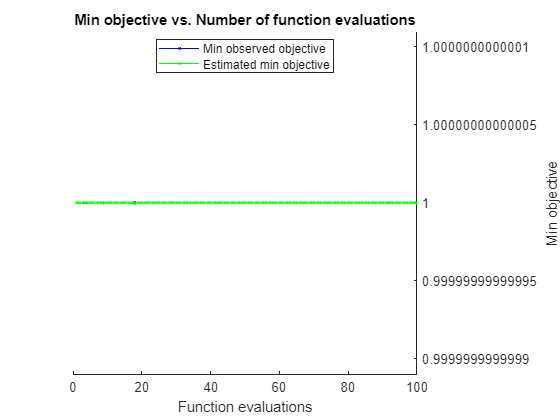


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 82.1449 seconds
Total objective function evaluation time: 28.7764

Best observed feasible point:
    Depth    numFilters    HiddenDimension    filterSizeS    paddingSizeS    dropoutLayerRegularization    miniBatchSize    learningrate
    _____    __________    _______________    ___________    ____________    __________________________    _____________    ____________

      5          7               30                3              3                   0.018905                  54            0.034971  

Observed objective function value = 1
Esti

maxEpochs = 30;
optimVars = [
    % Depth HiddenDimension paddingSizeS  dropoutLayerRegularization 
    optimizableVariable('Depth',[1 5],'Type','integer')
    optimizableVariable('numFilters',[1 8],'Type','integer')
    optimizableVariable('HiddenDimension',[2 32],'Type','integer')
    optimizableVariable('filterSizeS',[1 5],'Type','integer')
    optimizableVariable('paddingSizeS',[1 5],'Type','integer')
    optimizableVariable('dropoutLayerRegularization',[0.00 0.1],'Type','real')
    optimizableVariable('miniBatchSize',[8 128],'Type','integer')    
    optimizableVariable('learningrate',[1e-4 1e-1],'Type','real',"Transform","log")];

objectFunction = objectFunctionCovMix(trainDs, testDs,  maxEpochs);
    
% optimizer
BayesObject = bayesopt( objectFunction,             optimVars, ...
                        'MaxTime',                  24*60*60, ...
                        'Verbose',                  1,...
                        "UseParallel",              false,...
                        'IsObjectiveDeterministic', true, ...
                        'ParallelMethod',           "clipped-model-prediction",...
                        'MaxObjectiveEvaluations',  100,...
                        'ExplorationRatio',         0.6,...
                        'AcquisitionFunctionName', 'expected-improvement-per-second-plus');

optVars = bestPoint(BayesObject);

save("HyperParameterSearch\OptVars\CovMixoptVars.mat","optVars","-mat");

    % Evaluate and train the network with the optimal parameters
[valError,~,net, YPred, YTest] = BayesObject.ObjectiveFcn(optVars,1);

TX = {};
for k = 1:numel(testDs)
    TX{end+1} = testDs{k}{1};
end


TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(testDs{1})
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end

confusionchart(TY(:),Y(:),'Normalization','column-normalized');


        

for i = 100:-10:1
    try
        gpuDevice(1);
        options = trainingOptions('adam', ...
        'MaxEpochs',30, ...
        'MiniBatchSize',i, ...
        'InitialLearnRate',0.01, ...
        'LearnRateDropPeriod',5, ...
        'LearnRateDropFactor',0.5, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','training-progress',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
        net = trainNetwork(XTrain,YTrain,lgraph_2,options);
    catch ME
        disp(i);
        disp(ME)
    end
end

   100



  CNNException with properties:

    UnderlyingCause: [1×1 MException]
         identifier: 'nnet_cnn:cnn:layer:CustomLayer:PredictErrored'
            message: 'Error using the predict function in layer geluLayer. The function threw an error and could not be executed.'
              cause: {[1×1 MException]}
              stack: [2×1 struct]
         Correction: []



    90



  CNNException with properties:

    UnderlyingCause: [1×1 MException]
         identifier: 'nnet_cnn:cnn:layer:CustomLayer:PredictErrored'
            message: 'Error using the predict function in layer geluLayer. The function threw an error and could not be executed.'
              cause: {[1×1 MException]}
              stack: [2×1 struct]
         Correction: []



    80



  CNNException with properties:

    UnderlyingCause: [1×1 MException]
         identifier: 'nnet_cnn:cnn:layer:CustomLayer:PredictErrored'
            message: 'Error using the predict function in layer geluLayer. The function threw an error and could not be executed.'
              cause: {[1×1 MException]}
              stack: [2×1 struct]
         Correction: []



    70



  CNNException with properties:

    UnderlyingCause: [1×1 MException]
         identifier: 'nnet_cnn:cnn:layer:CustomLayer:PredictErrored'
            message: 'Error using the predict function in layer geluLayer. The function threw an error and could not be executed.'
              cause: {[1×1 MException]}
              stack: [2×1 struct]
         Correction: []



    60



  CNNException with properties:

    UnderlyingCause: [1×1 MException]
         identifier: 'nnet_cnn:cnn:layer:CustomLayer:PredictErrored'
            message: 'Error using the predict function in layer geluLayer. The function threw an error and could not be executed.'
              cause: {[1×1 MException]}
              stack: [2×1 struct]
         Correction: []



    50



  CNNException with properties:

    UnderlyingCause: [1×1 MException]
         identifier: 'nnet_cnn:cnn:layer:CustomLayer:PredictErrored'
            message: 'Error using the predict function in layer geluLayer. The function threw an error and could not be executed.'
              cause: {[1×1 MException]}
              stack: [2×1 struct]
         Correction: []



    40



  MException with properties:

    identifier: 'MATLAB:UndefinedFunction'
       message: 'Unrecognized function or variable 'lgraph_2'.'
         cause: {}
         stack: [1×1 struct]
    Correction: []



    30



  MException with properties:

    identifier: 'MATLAB:UndefinedFunction'
       message: 'Unrecognized function or variable 'lgraph_2'.'
         cause: {}
         stack: [1×1 struct]
    Correction: []



    20



  MException with properties:

    identifier: 'MATLAB:UndefinedFunction'
       message: 'Unrecognized function or variable 'lgraph_2'.'
         cause: {}
         stack: [1×1 struct]
    Correction: []



    10



  MException with properties:

    identifier: 'MATLAB:UndefinedFunction'
       message: 'Unrecognized function or variable 'lgraph_2'.'
         cause: {}
         stack: [1×1 struct]
    Correction: []

